close all
clear

composition = 1;

sigma=1;

% For Gaussian
fL=@(l) 1/sigma/sqrt(2*pi).*exp(-1/2*(l/sigma).^2);

l_min=-10;
l_step_size=0.01;
l_max=10;
l_grid=l_min:l_step_size:l_max;
fL_array=fL(l_grid);

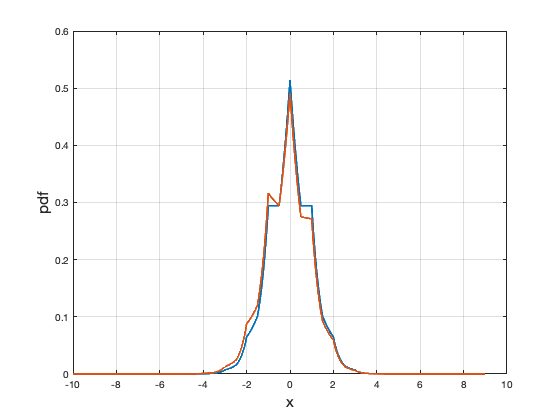

clear
%close all

% let the show begin!
% note that for a single composition, we can compute the Egamma directly.

composition = 100;
sen = 1;
subsampling=.1;
sigma=1;
noise_type=0;

switch noise_type
    case 0
        load(sprintf("cactus_pdf_d%.1f_L2_%.1f.mat",sen,sigma^2))
        x_grid=x(1:end-sen*n);
        x_max=max(x_grid);
        x_step_size=1/n;
        po=p(1:end-sen*n)/x_step_size;
        qo= subsampling*p(sen*n+1:end)/x_step_size+(1-subsampling)*po;
    otherwise
        % guassian
        if noise_type==1
            f = @(x) 1/sqrt(2*pi)/sigma*exp(-1/2*x.^2/sigma^2);
            % laplace
        else
            b=sigma/sqrt(2);
            f = @(x) 1/2/b*exp(-abs(x)/b);
        end
        % Take samples, and its shift/subsampled.
        x_max=sigma^2*20;
        x_step_size=2*x_max/1e4;
        n=1/x_step_size;
        x_grid=-x_max:x_step_size:x_max;
        po = f(x_grid);
        qo = subsampling*f(x_grid+sen)+(1-subsampling)*po;
end

% this right here is a hack! This code is not properly accounting for the tails of the distribution
po = po/(x_step_size*sum(po));
qo = qo/(x_step_size*sum(qo));

Eg=@(gamma) sum(x_step_size*max(0,po-gamma*qo));
% Eg = @(gamma) 1/2*(erfc((-1+2*sigma^2*log(gamma))/2/sqrt(2)/sigma)-...
%     gamma*erfc((1+2*sigma^2*log(gamma))/2/sqrt(2)/sigma));

figure
plot(x_grid,po,"LineWidth",2)
hold on
plot(x_grid,qo,"LineWidth",2)
xlabel('x','FontSize',15)
ylabel('pdf','FontSize',15)
grid on

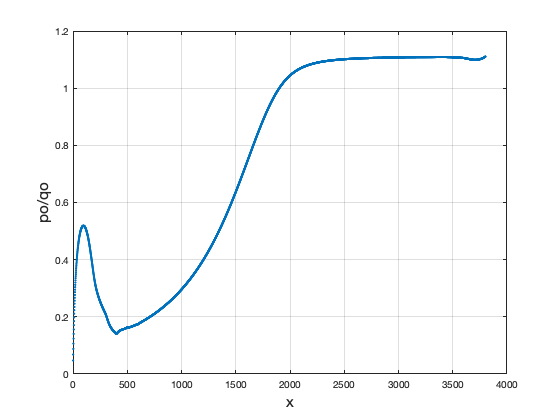


figure
plot((po./qo),'.',"LineWidth",2)
xlabel('x','FontSize',15)
ylabel('po/qo','FontSize',15)
grid on

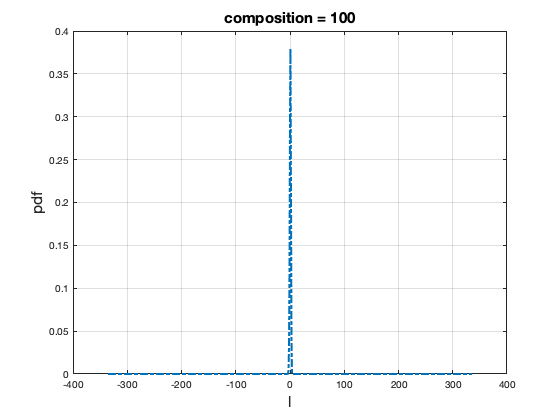


% Next, we sample the Egamma curve uniformly.
if noise_type==1
    gamma_max=exp(5);
    if subsampling~=1
        rate=po./qo;
        gamma_max=max(rate);
    end
else
    rate=po./qo;
    gamma_max=max(rate(1:end-n*sen));
end

gamma_step=gamma_max/1e3;
gamma_grid=0:gamma_step:gamma_max;

Eg_grid = arrayfun(Eg,gamma_grid); % samples uniform on Egamma curve
Eg_grid=[Eg_grid,Eg_grid(end)];

% q is the sencond order derivative
% we didn't divide gamma_step twice as this is discrete!
q1 = diff(Eg_grid,2)/gamma_step;
p1 = q1.* gamma_grid(2:end); % p is propotional to q
q1=[q1,0];
p1=[p1,1-sum(p1)];
p1=[p1,0];
q1=[q1,1-sum(q1)];

Egamma1 = @(gamma) sum(max(0,p1-gamma*q1));




% Now, instead of sample evenly on gamma, we sample uniformly on epsilon = log(gamma)
% Few things to note:
% (1) For gamma starts from 0, epsilon starts from some negetive value.
% (2) Since the sample is even on log(gamma), we also need dynamic step
% size on gamma. As the samples are dense on the left and loose on the
% right.

%eps_max = log(max(gamma_grid))*20;
eps_max = max(abs(log(po./qo)))*1.1;
eps_step = 2*eps_max/1000;

eps_grid=-eps_max:eps_step:eps_max; % define the lattice on epsilon
gamma_grid2 = exp(eps_grid); % convert it to gamma, now the gamma samples are uniform on log
Eg_grid2 = arrayfun(Eg,gamma_grid2);

% We are ready to compute the new (p3,q3) pairs, which is unifom on log(gamma)
aa =(Eg_grid2(3:end)-Eg_grid2(2:end-1))./(gamma_grid2(3:end)-gamma_grid2(2:end-1));
bb =(Eg_grid2(2:end-1)-Eg_grid2(1:end-2))./(gamma_grid2(2:end-1)-gamma_grid2(1:end-2));
% this was a little wrong. Here I'm fixing it
init_slope = (Eg_grid2(1)-1)/gamma_grid2(1);
q2 = (aa-bb);
q2 = [1+init_slope,bb(1)-init_slope,q2,-aa(end)];
p2=[0,q2(2:end).*gamma_grid2];
q2=[q2,0];
p2=[p2,max(0,1-sum(p2))];

% Again, we use Egamma3 for verifing the result, it should be an upper
% bound of the true Egamma curve.

Egamma2 = @(gamma) sum(max(0,p2-gamma*q2));



% get a lower bounding discrete model (p3,q3)
Egslope = @(gamma) -x_step_size*sum(qo(po>gamma*qo));

f_grid = zeros(size(gamma_grid2));
f_grid(1) = 1-gamma_grid2(1);
f_grid(end) = 0;
for i=2:length(f_grid)-1
    
    
    slp = (f_grid(end)-f_grid(i-1))/(gamma_grid2(end)-gamma_grid2(i-1));
    myfnc = @(t)(Eg(t)-f_grid(i-1))./(t-gamma_grid2(i-1))-Egslope(t);
    
    tmin = gamma_grid2(i-1)+eps(gamma_grid2(i-1));
    tmax = gamma_grid2(i);
    % should be that myfnc(tmin) > 0 and myfnc(tmax) < 0
    
    if myfnc(tmax) >= 0
        f_grid(i) = Eg(tmax);
    else
        if myfnc(tmin) <= 0
            slp = Egslope(gamma_grid2(i-1));
        else
            t = fzero(myfnc,[tmin,tmax]);
            slp = (Eg(t)-f_grid(i-1))./(t-gamma_grid2(i-1));
        end
        f_grid(i) = max(0,f_grid(i-1)+slp*(gamma_grid2(i)-gamma_grid2(i-1)));
    end
    
end


% The above produces a function that is not necessarily convex. Here we convexify it
gamma_grid_ext = [0,gamma_grid2];
f_grid_ext = [1,f_grid];
K = convhull(gamma_grid_ext,f_grid_ext);

slope = (f_grid_ext(K(2:end))-f_grid_ext(K(1:end-1)))./(gamma_grid_ext(K(2:end))-gamma_grid_ext(K(1:end-1)));
q3 = zeros(1,length(gamma_grid2));
q3(K(2:end-2)-1) = slope(2:end-1)-slope(1:end-2);
q3(end) = -slope(end-1);

p3 = q3.*(gamma_grid2(1:end));

Egamma3 = @(gamma) sum(max(0,p3-gamma*q3));


% Compute FFT bound from (p3,q3)
l_grid = eps_grid;
fL_array = p3;
N = length(l_grid);
l_step_size = eps_step;
l_max = max(l_grid);

% Before applying the FFT, we first pad the privacy loss pdf as we will use
% circular FFT in the code.
lenL=length(l_grid);
left=min(l_grid);
right=max(l_grid);
% I don't know why floor and ceil are here
%l_grid = floor(composition*min(l_grid)):l_step_size:ceil(composition*max(l_grid));
l_grid = composition*left:l_step_size:composition*right;
%fL_array=[zeros([1,floor((left-min(l_grid))/l_step_size)]),fL_array,zeros([1,ceil((max(l_grid)-right)/l_step_size)])];
%fL_array=[fL_array,zeros(1,length(l_grid)-length(fL_array))];

%T = pi/l_step_size;
%t_length=max(1e3,length(l_grid));
%t_step_size=2*T/t_length;

pO=fL_array;
%pOFFT = fft(pO*l_step_size);
% We can actually avoid all FFT shifting (and normalization) if we zero-pad at the end of 
% the vector, rather than on both sides. In fact the fft function will automatically do this
% if we just add a second argument with the desired length
pOFFT = fft(pO,length(l_grid));
cfFFT_array = pOFFT.^composition;
fLConvFFT_array = ifft(cfFFT_array);
fLConvFFT_array = max(0,fLConvFFT_array);





% fLConvFFT_array=fLConvFFT_array/sum(abs(fLConvFFT_array));
% 
% % the FFT curve is given as follows.
delta_FFT_lower_bd = @(eps) sum(fLConvFFT_array.*max(0,1-exp(eps-l_grid)));
%delta_FFT_lower_bd = @(eps) sum(full_conv.*max(0,1-exp(eps-l_grid)));

% And let's display the convoluted pdf
figure
plot(l_grid,abs(fLConvFFT_array)/l_step_size,'-.',...
    'LineWidth',2,'DisplayName','pdf conv');
%legend('FontSize',15)
xlabel('l','FontSize',15)
ylabel('pdf','FontSize',15)
title(sprintf('composition = %d',composition),'FontSize',15)
grid on

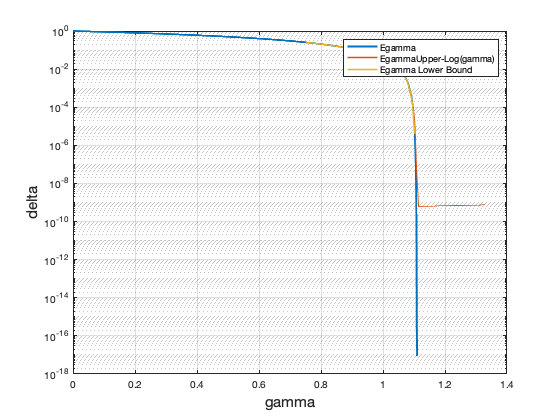




gamma_grid_test=0:gamma_step:gamma_max*1.2;
eps_max_test = log(max(gamma_grid_test));
eps_step_test = 2*eps_max_test/100;
eps_grid_test=-1*eps_max_test:eps_step_test:eps_max_test; % define the lattice on epsilon

Eg_array_upper1 = arrayfun(Egamma1,gamma_grid_test);
Eg_array_upper2 = arrayfun(Egamma2,exp(eps_grid_test));

Eg_array_lower = arrayfun(Egamma3,exp(eps_grid_test));

% Let's take a look.
figure

semilogy(gamma_grid_test,arrayfun(Eg,gamma_grid_test),...
    "LineWidth",2,"DisplayName","Egamma");

hold on

% semilogy(gamma_grid_test,Eg_array_upper1,'--D',...
%     "LineWidth",1.5,'DisplayName','EgammaUpper-gamma',...
%     'MarkerIndices',1:ceil(length(gamma_grid_test)/20):length(gamma_grid_test));
% hold on

%plot(exp(eps_grid_test),Eg_array_upper2,'-o','MarkerIndices',1:1:length(eps_grid_test),...
%    "LineWidth",1.5,'DisplayName','EgammaUpper-Log(gamma)');
semilogy(exp(eps_grid_test),Eg_array_upper2,"LineWidth",1.5,'DisplayName','EgammaUpper-Log(gamma)');
hold on

semilogy(exp(eps_grid_test),Eg_array_lower,"LineWidth",1.5,'DisplayName','Egamma Lower Bound');


xlabel("gamma",'FontSize',15);
ylabel("delta",'FontSize',15);
%legend('FontSize',15);
legend;
%axis([0 10 0 1]);
grid on;

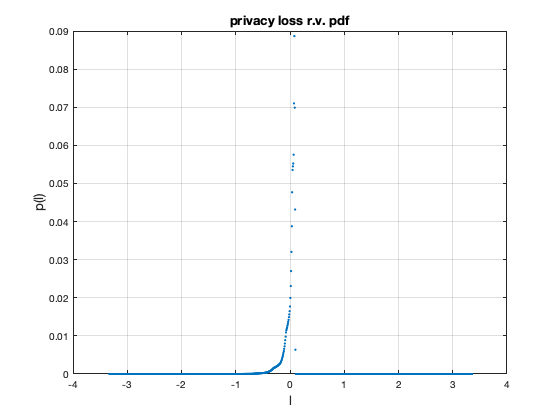


%l_grid=log(p2./q2);
%l_grid=l_grid(1:end-3);
%p2=p2(1:end-3); % why do we do this?
%ps=abs(p2)/sum(abs(p2));
%l_step_size=(max(l_grid)-min(l_grid))/(length(l_grid)-1);
l_step_size = eps_step;
ps = p2;
ps=ps/l_step_size; % we convert it to samples on the pdf

fL_array=p2(2:end-1);

% However, there could be some NaN points on the original x_grid, we fill
% the holes like this
%l_grid = min(l_grid):l_step_size:max(l_grid);
l_grid = eps_grid;
N = length(l_grid);

% And we take fewer samples
% l_grid=l_grid(1:1:end);
% fL_array=fL_array(1:1:end);
% l_step_size=l_grid(2)-l_grid(1); % renewed step size on x
% l_max=max(l_grid);

fL=@(l) 1/sigma/sqrt(2*pi).*exp(-1/2*(l/sigma).^2);

% Let's take a look the pdf of plrv!
figure
plot(l_grid(5:end),abs(fL_array(5:end)),'.',"LineWidth",2);
title("privacy loss r.v. pdf","Fontsize",13)
xlabel("l","Fontsize",13)
ylabel("p(l)","Fontsize",13)
grid on

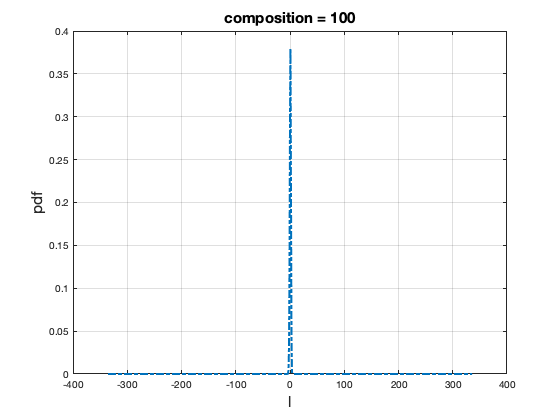

% % THIS BLOCK IS FOR TESTING ONLY!
% % For Gaussian
% fL=@(l) 1/sigma/sqrt(2*pi).*exp(-1/2*(l/sigma).^2);
% fL_array=fL(l_grid-0.5);
%
% % Let's take a look the pdf of plrv!
% figure
% plot(l_grid,abs(fL_array),'.',"LineWidth",2);
% title("privacy loss r.v. pdf","Fontsize",13)
% xlabel("l","Fontsize",13)
% ylabel("p(l)","Fontsize",13)
% grid on

% The whole idea here is the following: we first derive the approximate
% (P,Q) pair which has the same E-gamma curve but also has nice bijictive
% properties that leads to the (approximate) privacy loss random variable,
% then we are ready to apply the FFT to compute the convoluted pdf to deal
% with compositions.

% Before applying the FFT, we first pad the privacy loss pdf as we will use
% circular FFT in the code.

lenL=length(l_grid);
left=min(l_grid);
right=max(l_grid);
l_grid = composition*left:l_step_size:composition*right;
%l_grid = floor(composition*min(l_grid)):l_step_size:ceil(composition*max(l_grid));
fL_array=[zeros([1,round((left-min(l_grid))/l_step_size)]),fL_array,zeros([1,round((max(l_grid)-right)/l_step_size)])];

% figure
% plot(l_grid,abs(fL_array),'.',"LineWidth",2);
% title("privacy loss r.v. pdf","Fontsize",13)
% xlabel("l","Fontsize",13)
% ylabel("p(l)","Fontsize",13)
% grid on
% Now, let's perform integration to obtain the c.f. So we first define the
% lattice on T (frequency domain).

% T = pi/l_step_size;
% t_length=max(1e3,length(l_grid));
% % T_length=length(x_grid);
% t_step_size=2*T/t_length;
% t_grid = -1*T:t_step_size:1*T-t_step_size;

% this is the c.f. by discrete integration

a = 0.5;

% % numerical c.f.
% cfDiscrete= @(t) sum(l_step_size*fL_array.*exp(l_grid.*(1i*t))).^composition;
% cfDiscrete_array = arrayfun(cfDiscrete,t_grid);

% fLConvDiscrete= @(l) 1/sqrt(length(cfDiscrete_array))*sum(cfDiscrete_array.*exp(t_grid.*(-1i*l)));
% fLConv_array = arrayfun(fLConvDiscrete,l_grid);
%
% figure
% % plot(l_grid,fL_array);
% % hold on
% plot(l_grid,fLConv_array,'--');

% % numerical tilted c.f.
% cfTiltDiscrete = @(t) sum(l_step_size*fL_array.*exp(l_grid.*(a+1i*t))).^composition;
% cfTiltDiscrete_array = arrayfun(cfTiltDiscrete,t_grid);

% % edgeworth c.f.
% s=6;
% [moment, cumulant, lambda, rho]=cumulants_generatorDiscrete(ps,x_grid,s);
% cfTiltEdgeworth = @(t) edgeworth_CharFn(a,t,s,lambda,composition);
% cfTiltEdgeworth_array = arrayfun(cfTiltEdgeworth,t_grid);

% let's try to use FFT, and shift it to the center.
% pTilt=fL_array.*exp(a*l_grid);
% pTilt_padding=[pTilt,zeros([1,t_length-length(pTilt)])];
% pTiltFFT = fft(pTilt_padding*l_step_size);
% cfTiltFFT_array = (fftshift(pTiltFFT)).^composition;


% There's a minor problem with the upper bounding model, since the last value has q2(end)=0 but
% p2(end)>0. This correspondings to an infinite value of L, which doesn't show up in the grid.
% We can deal with this by slicing off the last value, then adding back to delta the probability 
% that any of the compositions happens to hit the last value. This occurs with probability
% 1-(1-p2(end))^composition
pO=p2(2:end-1);
pOFFT = fft(pO,length(l_grid));
cfFFT_array = pOFFT.^composition;
fLConvFFT_array = ifft(cfFFT_array);
fLConvFFT_array = max(0,fLConvFFT_array);


%pOFFT = fft(pO*l_step_size);
%cfFFT_array_unShifted = pOFFT.^composition;
%cfFFT_array = (fftshift(pOFFT)).^composition;

%fLConvFFT_array = ifftshift(abs(ifft(cfFFT_array.*t_step_size)));
% fLConvFFT_array = (abs(ifft(cfFFT_array_unShifted.*t_step_size)));

%fLConvFFT_array=fLConvFFT_array/sum(abs(fLConvFFT_array));

% the FFT curve is given as follows.
delta_FFT = @(eps) sum(fLConvFFT_array.*max(0,1-exp(eps-l_grid)))+(1-(1-p2(end))^composition);
%delta_FFT = @(eps) sum(full_conv.*max(0,1-exp(eps-l_grid)))+(1-(1-p2(end))^composition);


% And let's display the convoluted pdf
figure
plot(l_grid,abs(fLConvFFT_array)/l_step_size,'-.',...
    'LineWidth',2,'DisplayName','pdf conv');
%legend('FontSize',15)
xlabel('l','FontSize',15)
ylabel('pdf','FontSize',15)
title(sprintf('composition = %d',composition),'FontSize',15)
grid on

% % let's take a look of the characteristic functions.
%
% figure
%
% % semilogy(t_grid, abs(cfDiscrete_array),'-',"LineWidth",1.5,...
% %     "DisplayName","cfDiscrete");
% % hold on
% %
% % semilogy(t_grid, abs(cfFFT_array),'-',"LineWidth",1.5,...
% %     "DisplayName","cfFFT")
% % hold on
%
% % semilogy(t_grid, abs(cfTiltDiscrete_array),'-',"LineWidth",1.5,...
% %     "DisplayName","cfTiltDiscrete")
% % hold on
%
% % semilogy(t_grid, abs(cfTiltFFT_array),"LineWidth",1.5,...
% %     "DisplayName","cfTiltFFT")
% % hold on
%
% % semilogy(t_grid, abs(cfTiltEdgeworth_array),"LineWidth",1.5,...
% %     "DisplayName","cfTiltEdgeworth")
% % hold on
%
% % semilogy(t_grid,abs(real(cfTiltFFT_array)-real(cfTiltDiscrete_array)),'--',"LineWidth",1,...
% %     "DisplayName","Abs Error")
%
% xlabel("t","FontSize",13);
% title(sprintf("characteristic function with %d composition",composition),"FontSize",13);
% legend
% grid on


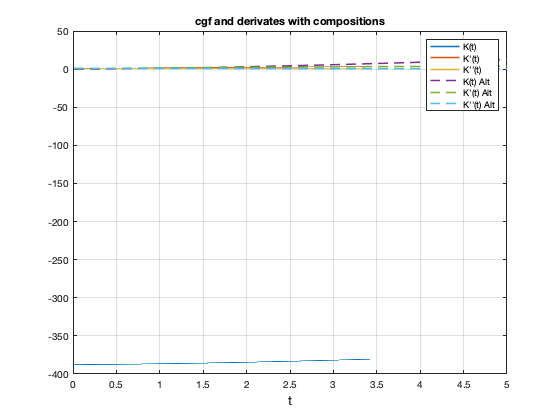

% With FFT delta curve as a baseline, now we derive the saddle-point
% curves. Basically there are two approaches, one is directly from the
% orignal noise distributions, one is from the convoluted pdf (FFT).

a_grid=1e-2:1e-2:5;
eps_grid_test = linspace(1e-10,15,20);

EexptL=@(t) sum(l_step_size*fL_array.*exp(t*l_grid));

fLTilt=@(t) exp(t*l_grid).*fL_array/EexptL(t);

K = @(t,n) n*log(EexptL(t));

K1 = @(t,n) n*sum(l_step_size*fL_array.*l_grid.*exp(t*l_grid))./EexptL(t);

K2 = @(t,n) n*(sum(l_step_size*fL_array.*l_grid.^2.*exp(t*l_grid))./EexptL(t)-K1(t,1).^2);

g = @(x,t) exp(-t*x).*max(0,1-exp(-x));
g1 = @(x,t) exp(-t*x)*(-t+(t+1).*exp(-x));
x0 = @(t)-log(t./(t+1));
gmax= @(t) t.^t./(t+1).^(t+1);

C=6;
ELTilt = @(t) sum(l_step_size*l_grid.*fLTilt(t));
T = @(t,n) sum(l_step_size*fLTilt(t).*abs(l_grid-ELTilt(t)).^3)*n;

% delta0 = @(eps) sum(l_step_size*fL_array.*max(0,1-exp(eps-l_grid)));
% delta23 = @(eps,t,n) exp(K(t,n)-eps*t)*(exp(K2(t,n)*t^2/2-t*(K1(t,n)-eps))*qfunc(sqrt(K2(t,n))*t-(K1(t,n)-eps)/sqrt(K2(t,n)))...
%     -exp(K2(t,n)*(t+1)^2/2-(t+1)*(K1(t,n)-eps))*qfunc(sqrt(K2(t,n))*(t+1)-(K1(t,n)-eps)/sqrt(K2(t,n)))...
%     +2*gmax(t)*C*T(t,n)/(K2(t,n)^(3/2)));

delta27 = @(eps,t,n) exp(K(t,n)-eps*t)*(1/sqrt(2*pi*K2(t,n))/t/(t+1));
error = @(t,n) 2*gmax(t)*T(t,n)*t*(t+1)/K2(t,n)*C;

t_list=zeros(length(eps_grid_test),1);
for i =1:length(eps_grid_test)
    [val,ind]=min(arrayfun(@(t) delta27(eps_grid_test(i),t,composition).*(1+error(t,composition)), a_grid));
    t_list(i)=a_grid(ind);
end

delta_27=zeros(length(eps_grid_test),1);
for i = 1:length(eps_grid_test)
    delta_27(i)=delta27(eps_grid_test(i),t_list(i),composition);
end

error_array=arrayfun(@(t) error(t,composition),t_list);


% Alternative, we can directly compute the K functions with original
% distributions.

if noise_type~=0
    n=200;
    x_grid2=-8:0.005:8;
    ps = f(x_grid2)*0.005;
    qs = subsampling*f(x_grid2+sen)*0.005+(1-subsampling)*ps;
    ps=ps';
    qs=qs';
    
else
    shift_steps = ceil(n*sen);
    
    ps=p(1:end-shift_steps);
    %     ps=ps';
    qs= subsampling*p(shift_steps+1:end)+(1-subsampling)*ps;
    %     qs=qs';
    %     ps = [p ; zeros(shift_steps,1)];
    %     qs = subsampling*[zeros(shift_steps,1); p]+(1-subsampling)*ps;
end


mgf = @(t) sum(ps.*(ps./(qs+1e-20)).^t);
logmgf = @(t) log(sum(ps.*(ps./(qs+1e-20)).^t));
KB = @(t,n) n*logmgf(t);
K1B = @(t,n) n*sum(ps.*log(ps./(qs+1e-20)).*(ps./(qs+1e-20)).^t)/mgf(t);
K2B = @(t,n) n*(sum(ps.*(log(ps./(qs+1e-20))).^2.*(ps./(qs+1e-20)).^t)/mgf(t)-K1B(t,1).^2);

figure;
plot(a_grid,arrayfun(@(t) K(t,composition),a_grid),"LineWidth",1.5,"DisplayName","K(t)");
hold on
plot(a_grid,arrayfun(@(t) K1(t,composition),a_grid),"LineWidth",1.5,"DisplayName","K'(t)");
hold on
plot(a_grid,arrayfun(@(t) K2(t,composition),a_grid),"LineWidth",1.5,"DisplayName","K''(t)");
hold on

plot(a_grid,arrayfun(@(t) KB(t,composition),a_grid),'--',"LineWidth",1.5,"DisplayName","K(t) Alt");
hold on
plot(a_grid,arrayfun(@(t) K1B(t,composition),a_grid),'--',"LineWidth",1.5,"DisplayName","K'(t) Alt");
hold on
plot(a_grid,arrayfun(@(t) K2B(t,composition),a_grid),'--',"LineWidth",1.5,"DisplayName","K''(t) Alt");
xlabel("t","FontSize",13)
title('cgf and derivates with compositions')
%legend("FontSize",13)
legend;
grid on


% delta27B = @(eps,t,n) exp(KB(t,n)-eps*t)*(1/sqrt(2*pi*K2B(t,n))/t/(t+1));
% errorB = @(t,n) 2*gmax(t)*T(t,n)*t*(t+1)/K2B(t,n)*C;
% 
% t_listB=zeros(length(eps_grid_test),1);
% for i =1:length(eps_grid_test)
%     [val,ind]=min(arrayfun(@(t) delta27B(eps_grid_test(i),t,composition).*(1+errorB(t,composition)), a_grid));
%     t_listB(i)=a_grid(ind);
% end
% 
% delta_27B=zeros(length(eps_grid_test),1);
% for i = 1:length(eps_grid_test)
%     delta_27B(i)=delta27B(eps_grid_test(i),t_listB(i),composition);
% end
% 
% error_arrayB=arrayfun(@(t) error(t,composition),t_listB);

% In this block, we no longer relay on the approximate (P,Q) pair, rather
% we use the original noise distributions to obtain the moment/cumulant
% generating functions.

% Saddlepoint

logmgf = @(t) log(sum(ps.*((ps./(qs+1e-20))).^t));
fSP = chebfun(@(t) composition*logmgf(t)-log(t)-log(1+t), [1e-2,100],'splitting','on');
fSP_diff = diff(fSP);
fSP_hess = diff(fSP,2);
delta_SP_array = zeros(length(eps_grid_test),1);
for i=1:length(eps_grid_test)
    eps = eps_grid_test(i);
    x0 = roots(fSP_diff-eps);
    temp = exp(fSP(x0)-eps*x0)/sqrt(abs(fSP_hess(x0)))/sqrt(2*pi);
    if isempty(temp)
        delta_SP_array(i) = 0;
    else
        delta_SP_array(i)=temp;
    end
end

% logmgf = @(t) log(sum(ps.*((ps./(qs+1e-20))).^t));
% fSP = chebfun(@(t) composition*logmgf(t), [1e-30,10],'splitting','on');
% fSP_diff = diff(fSP);
% fSP_hess = diff(fSP,2);
% delta_SP_array = zeros(length(eps_grid_test),1);
% for i=1:length(eps_grid_test)
%     eps = eps_grid_test(i);
%     x0 = roots(fSP_diff-eps);
%     if isempty(x0)
%         delta_SP_array(i)=0;
%     else
%         temp = exp(fSP(x0)-eps*x0)/sqrt(abs(fSP_hess(x0)))/sqrt(2*pi)/x0/(x0+1);
%         delta_SP_array(i)=temp;
%     end
% end


% Plancherel

a = 0.01;
lims =  [-50,50];
mgf = @(t) (sum(ps.*((ps./(qs+1e-30))).^t));
f2 = chebfun(@(t) (mgf(a+1i*t)), lims,'splitting','on');
filter = chebfun(@(t) 1/((a+1i*t).*(a+1i*t+1)),lims,'splitting','on' );
t = chebfun('t',lims,'splitting','on');
delta_cf_array = zeros(length(eps_grid_test),1);
for i=1:length(eps_grid_test)
    eps = eps_grid_test(i);
    delta_cf_array(i) = real(exp(-eps*a)*sum((f2.^composition)*exp(-eps*(1i*t))*filter)/(2*pi));
end


% Moments accountant

alpha_max = 30; %maximum lambda in MGF
fMA = chebfun(@(t) logmgf(t), [0,alpha_max],'splitting','on');
alpha_grid = chebfun(@(t) t, [0,alpha_max],'splitting','on');
delta_MA_array = zeros(length(eps_grid_test),1);
for i=1:length(eps_grid_test)
    eps = eps_grid_test(i);
    delta_MA_array(i) = exp(min(composition*fMA-eps*alpha_grid));
end


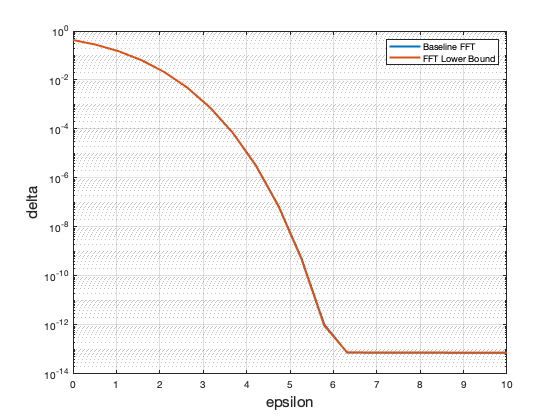


figure

eps_grid_test = linspace(1e-10,10,20);

% semilogy(eps_grid_test,delta_MA_array,'-.',...
%     "LineWidth",2,"DisplayName","Moments Accountant")
% hold on

% if composition==1
%     semilogy(eps_grid_test,arrayfun(Eg,exp(eps_grid_test)),'-.',...
%         "LineWidth",2,"DisplayName","Original Egamma")
%     hold on
%
%     semilogy(eps_grid_test,arrayfun(Egamma2,exp(eps_grid_test)),'--o',...
%         "LineWidth",1.5,"DisplayName","Upper Egamma",'MarkerIndices',1:20:length(eps_grid_test))
%     hold on
% end

semilogy(eps_grid_test,arrayfun(delta_FFT,eps_grid_test),...
    "LineWidth",2,"DisplayName","Baseline FFT")
hold on

semilogy(eps_grid_test,arrayfun(delta_FFT_lower_bd,eps_grid_test),...
    "LineWidth",2,"DisplayName","FFT Lower Bound")
hold on

% semilogy(eps_grid_test,delta_cf_array,'-.',...
%     "LineWidth",2,"DisplayName","cf-filter")
% hold on
% 
% semilogy(eps_grid_test,delta_SP_array,'-.',...
%     "LineWidth",2,"DisplayName","Saddlepoint")
% hold on

% semilogy(eps_grid_test,delta_27,'--D',...
%     "LineWidth",1.5,"DisplayName","Base Term")
% hold on
% 
% semilogy(eps_grid_test,delta_27.*(1+error_array),'--D',...
%     "LineWidth",1.5,"DisplayName","Base Term with Error")
% hold on

% semilogy(eps_grid_test,abs(delta_27B),'-+',...
%     "LineWidth",1.5,"DisplayName","Base Term (Alt)")
% hold on
% 
% semilogy(eps_grid_test,abs(delta_27B.*(1+error_arrayB)),'-+',...
%     "LineWidth",1.5,"DisplayName","Base Term with Error (Alt)")
% hold on

xlabel("epsilon",'FontSize',15)
ylabel('delta','FontSize',15)
%legend('FontSize',15)
legend;
grid on

error_n_array=[];
t_array=[];
n_grid=linspace(1,100,20);
for n=n_grid
    [val,ind]=min(arrayfun(@(t) delta27(10,t,n).*(1+error(t,n)), t_grid));
    t_temp=t_grid(ind);
    t_array=[t_array,t_temp];
    temp=error(t_temp,n);
    error_n_array=[error_n_array,temp];
end


figure
plot(n_grid,error_n_array,'LineWidth',1.5)
xlabel('composition n','FontSize',15)
ylabel('error','FontSize',15)
grid on

figure
plot(n_grid,t_array,'LineWidth',1.5)
xlabel('composition n','FontSize',15)
ylabel('t(n)','FontSize',15)
grid on


n_grid=linspace(1,1000,20);
[N,Eps]=meshgrid(n_grid,eps_grid_test);
error_n_grid=arrayfun(@(n,eps) minError(delta27,error,n,eps,t_grid),N,Eps);


figure
surf(N,Eps,(error_n_grid))
xlabel('composition n','FontSize',15)
ylabel('epsilon','FontSize',15)
zlabel('error','FontSize',15)
grid on

function y=minError(delta27,error,n,eps,t_grid)
[val,ind] = min(arrayfun(@(T) delta27(eps,T,n).*(1+error(T,n)), t_grid));
y=error(t_grid(ind),n);
end